# Figure S4J

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'F068_data.mat'],'S','settings','allIF');

conditions = settings.conditions

conditions = 16×5 cell array
    {'NR75 DMSO DMSO'      }    {[1 2 3 4]}    {[2]}    {[1]}    {[1]}
    {'NR75 DMSO TAK'       }    {[1 2 3 4]}    {[3]}    {[1]}    {[1]}
    {'NR75 DMSO 4/6i'      }    {[1 2 3 4]}    {[4]}    {[1]}    {[1]}
    {'NR75 DMSO 4/6i + TAK'}    {[1 2 3 4]}    {[5]}    {[1]}    {[1]}
    {'NR75 DOX DMSO'       }    {[1 2 3 4]}    {[6]}    {[1]}    {[1]}
    {'NR75 DOX TAK'        }    {[1 2 3 4]}    {[7]}    {[1]}    {[1]}
    {'NR75 DOX 4/6i'       }    {[1 2 3 4]}    {[8]}    {[1]}    {[1]}
    {'NR75 DOX 4/6i + TAK' }    {[1 2 3 4]}    {[9]}    {[1]}    {[1]}
    {'NR77 DMSO DMSO'      }    {[5 6 7 8]}    {[2]}    {[1]}    {[1]}
    {'NR77 DMSO TAK'       }    {[5 6 7 8]}    {[3]}    {[1]}    {[1]}
    {'NR77 DMSO 4/6i'      }    {[5 6 7 8]}    {[4]}    {[1]}    {[1]}
    {'NR77 DMSO 4/6i + TAK'}    {[5 6 7 8]}    {[5]}    {[1]}    {[1]}
    {'NR77 DOX DMSO'       }    {[5 6 7 8]}    {[6]}    {[1]}    {[1]}
    {'NR77 DOX TAK'        }    {[5 6 7 8]}    {

framesPerHr = 60/12;
 frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
    S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end
drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

for i = 1:length(S)
    dat = S(i);
   
    
    cdkHighGate = false(length(dat.POI(:,1)),1);
    cdkLowGate = false(length(dat.POI(:,1)),1);
     cdkGateAll = false(length(dat.POI(:,1)),1);
crlGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
      
        if dat.POI(n,1) > 1 * framesPerHr
            crlGate(n) = dat.crlNuc(n,dat.POI(n,1) - 1 * framesPerHr) >  100;
        end

    end
  
       S(i).cdkGateAll = cdkGateAll;
%     S(i).cdkGate = cdkGate;
   S(i).crlGate = crlGate;
        S(i).cdkHighGate = cdkHighGate;
         S(i).cdkLowGate = cdkLowGate;

end

S4J left

conds=[9 11 15];
timeGate = [0 10];
colors = [.5 .5 .5; .1 .4 1; .6 .9 .2;.9 .4 0;1 .6 0; 1 .3 .2; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
   
    inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
         S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1);
sum(inds)
    ydata = data.sigNuc(inds,:);
    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5});
end

ans = 2556

ans = 1380

ans = 2575

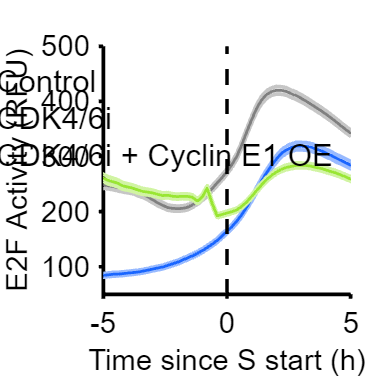


ylabel({'E2F Activity (RFU)'});
xlabel('Time since S start (h)');
legend('Control','CDK4/6i','CDK4/6i + Cyclin E1 OE','box','off','Location','northeast','fontsize',17);

xlim([-5 5]); 
ylim([50 500]);

vline([0],'k--')

% print_pdf(['fig_S4Jleft.pdf'])


S4J right

conds=[9 11 15];
timeGate = [0 10];
colors = [.5 .5 .5; .1 .4 1; .6 .9 .2;.9 .4 0;1 .6 0; 1 .3 .2; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
figure('unit','inches','position',[0 0 4 4])
hold on
axis square;

POI_align = 1;
POI_cal = 3;
data_out = [];
frames_out = [];

for i=1:length(conds)
    data = S(conds(i));
       inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
         S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1);

     mat = NaN * ones(size(data.area));
    event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

     y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 

    plot(x,f,'Color',colors(i,:),'linewidth',2);
 
    sum(inds)
end

ans = 3229

ans = 2926

ans = 3304

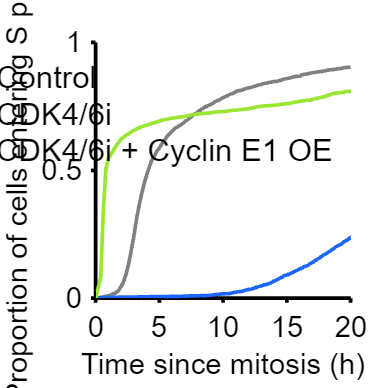



axis square
set(gca,'linewidth',2,'fontsize',16)
legend('Control','CDK4/6i','CDK4/6i + Cyclin E1 OE','box','off','Location','northeast','fontsize',17);
xlim([0 20]); 
xticks(0:5:20)
ylim([0 1]);
xlabel('Time since mitosis (h)','FontSize',16)
ylabel('Proportion of cells entering S phase','FontSize',16)
hold on

% print_pdf(['fig_S4Jright.pdf'])
